# Problema 4

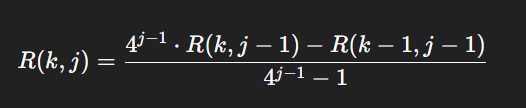

function [rezultat, matrice_romberg] = romberg_custom(f, a, b, tol, max_iter)
% INPUT:
%   f         - functia de integrat (fara pondere)
%   a, b      - capetele intervalului de integrare
%   tol       - toleranta maxima admisa pentru eroare absoluta
%   max_iter  - (optional) numar maxim de iteratii (default: 10)
%
% OUTPUT:
%   rezultat         - valoarea aproximata a integralei
%   matrice_romberg  - matricea completa R(i, j) cu aproximari intermediare

    if nargin < 5
        max_iter = 10;  % daca nu se specifica, folosim 10 iteratii maxim
    end

    matrice_romberg = zeros(max_iter);  % initializare matrice patratica
    h = b - a;  % lungimea initiala a intervalului

    % R(1,1): regula trapezului de baza (1 singur trapez)
    matrice_romberg(1,1) = h / 2 * (f(a) + f(b));

    for k = 2:max_iter
        h = h / 2;  % la fiecare pas, injumatatim pasul

        % calculam suma punctelor noi dintre cele deja folosite
        suma = 0;
        for i = 1:2^(k-2)
            x_i = a + (2*i - 1) * h;
            suma = suma + f(x_i);
        end

        % R(k,1): aproximare cu regula trapezului compus
        matrice_romberg(k,1) = 0.5 * matrice_romberg(k-1,1) + h * suma;

        % extrapolare Richardson pentru R(k,j)
        for j = 2:k
            matrice_romberg(k,j) = (4^(j-1) * matrice_romberg(k,j-1) - matrice_romberg(k-1,j-1)) / ...
                                   (4^(j-1) - 1);
        end

        % criteriu de oprire: diagonala principala converge
        if abs(matrice_romberg(k,k) - matrice_romberg(k-1,k-1)) < tol
            rezultat = matrice_romberg(k,k);
            return;
        end
    end

    % daca nu s-a atins toleranta dupa max_iter iteratii
    warning('Romberg: nu s-a atins toleranta dupa %d iteratii.', max_iter);
    rezultat = matrice_romberg(max_iter, max_iter);
end

Matricea romberg

- Linia 1 (R(1,1)): o estimare brută cu **1 trapez** pe intervalul [a, b]

- Linia 2 (R(2,1)): aceeași formulă, dar cu **2 trapeze**

- Linia 3 (R(3,1)): cu **4 trapeze**

f = @(x) exp(-x.^2);     % functie de integrat
a = 0;
b = 1;
eps = 1e-8;

[rez_romberg, R] = romberg_custom(f, a, b, eps);

Rezultat Romberg: 0.7468241328


Valoare exacta (aprox.): 0.7468241328


fprintf('Rezultat Romberg: %.10f\n', rez_romberg);
fprintf('Valoare exacta (aprox.): %.10f\n', integral(f, a, b, 'AbsTol', eps));

Matricea Romberg calculata:


    0.6839         0         0         0         0         0         0         0         0         0
    0.7314    0.7472         0         0         0         0         0         0         0         0
    0.7430    0.7469    0.7468         0         0         0         0         0         0         0
    0.7459    0.7468    0.7468    0.7468         0         0         0         0         0         0
    0.7466    0.7468    0.7468    0.7468    0.7468         0         0         0         0         0
    0.7468    0.7468    0.7468    0.7468    0.7468    0.7468         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0 

disp('Matricea Romberg calculata:');
disp(R);